Total number of read CIR pairs for L1_R1_CIRs_Ch_9.txt: 223


CIR number 1 for L1_R1_CIRs_Ch_9.txt


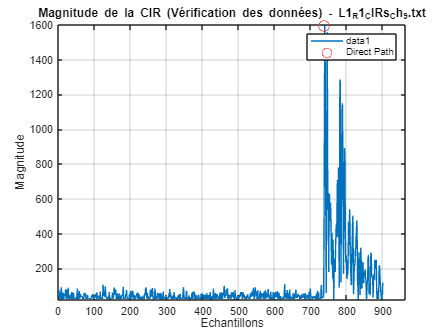

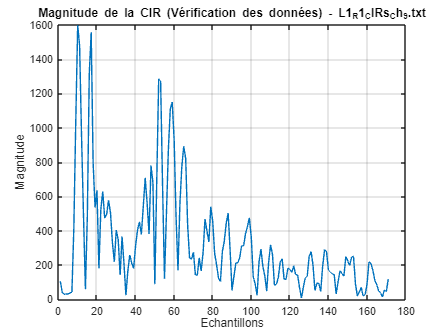

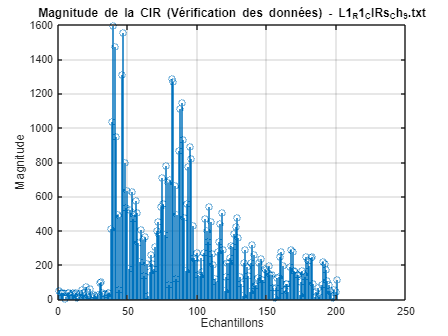

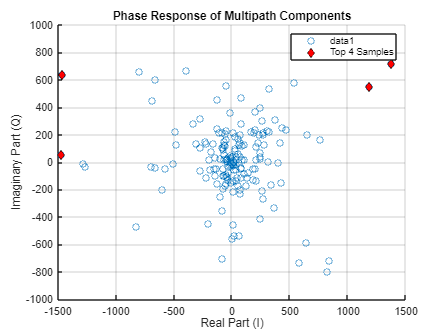

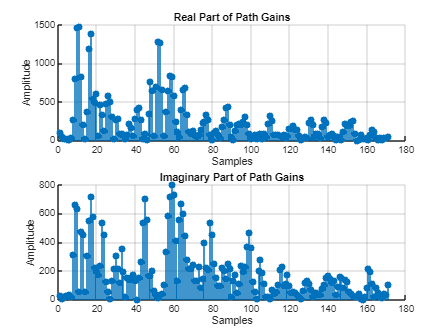

CIR number 2 for L1_R1_CIRs_Ch_9.txt


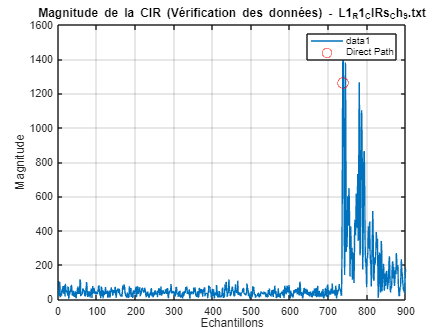

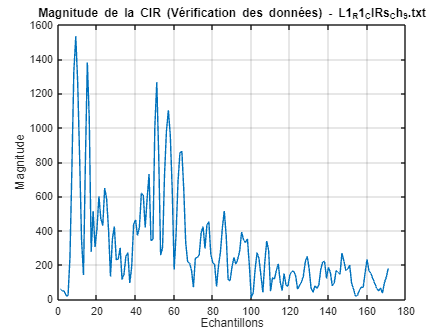

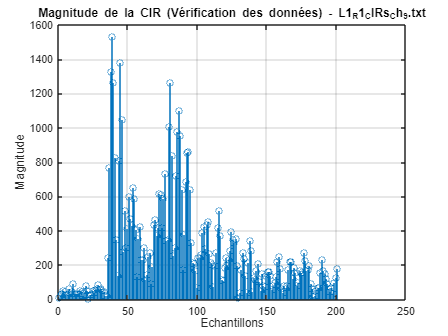

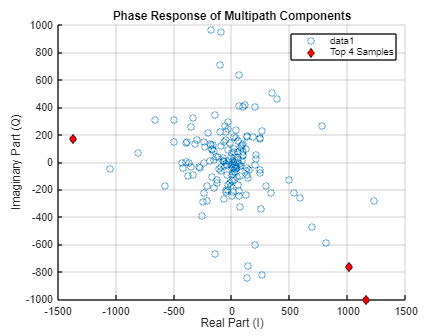

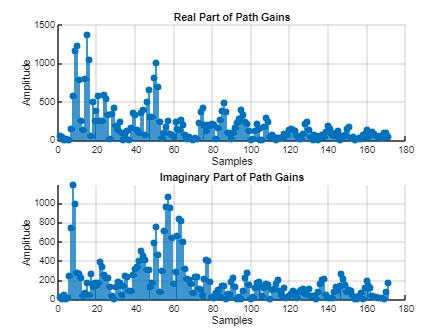

CIR number 3 for L1_R1_CIRs_Ch_9.txt


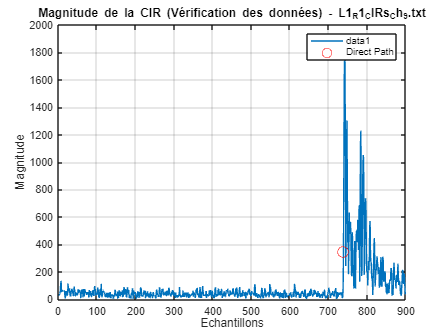

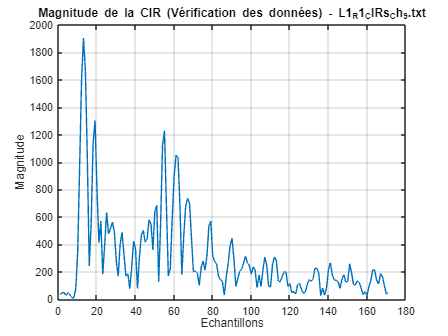

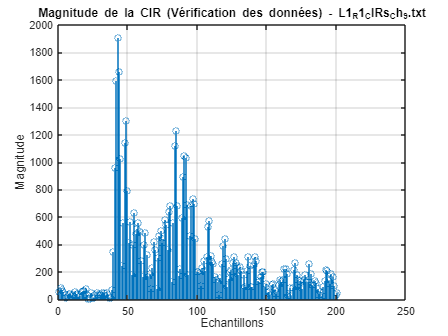

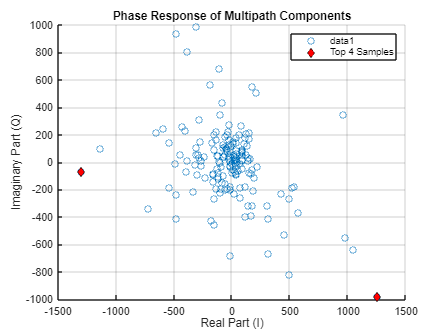

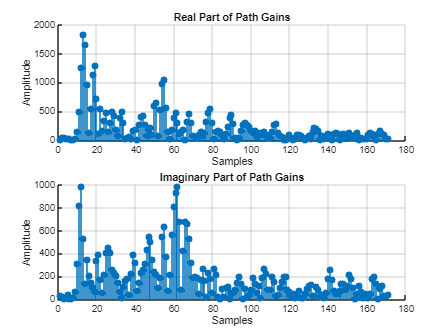

CIR number 4 for L1_R1_CIRs_Ch_9.txt


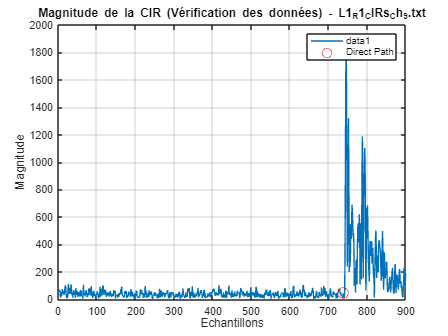

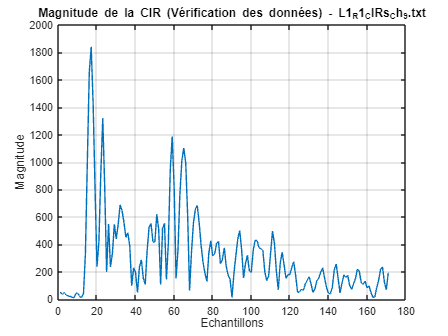

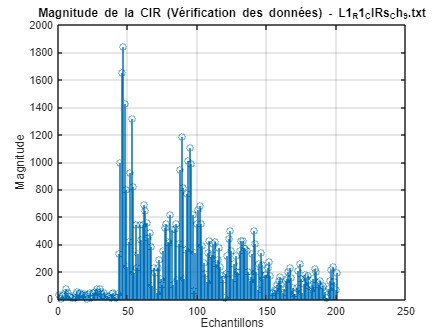

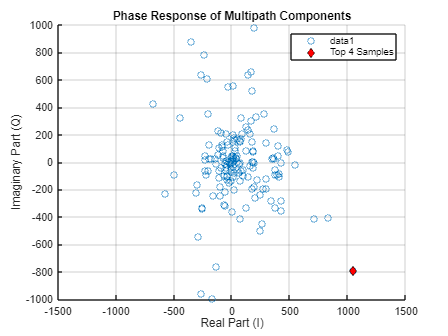

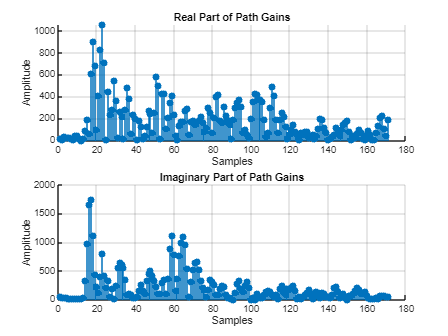

CIR number 5 for L1_R1_CIRs_Ch_9.txt


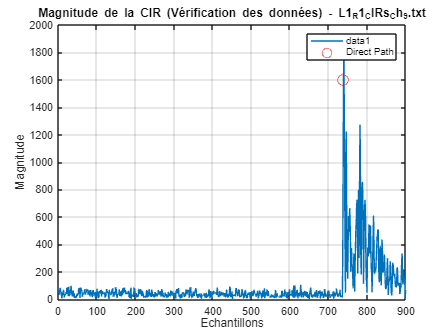

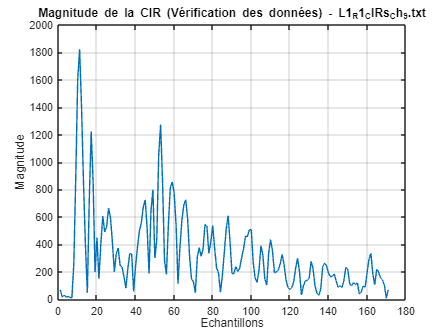

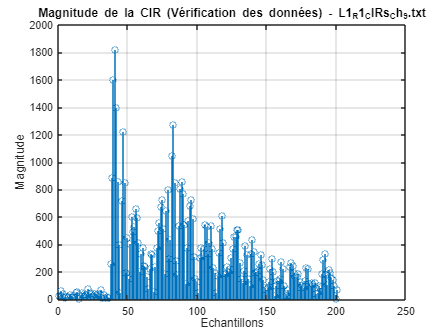

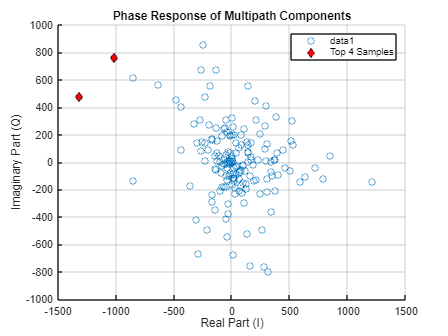

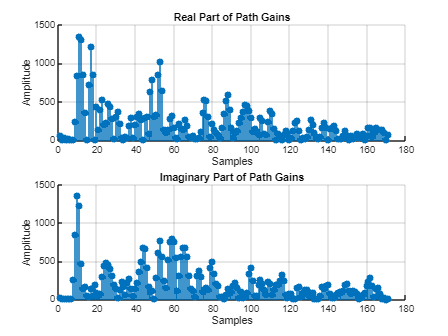

CIR number 6 for L1_R1_CIRs_Ch_9.txt


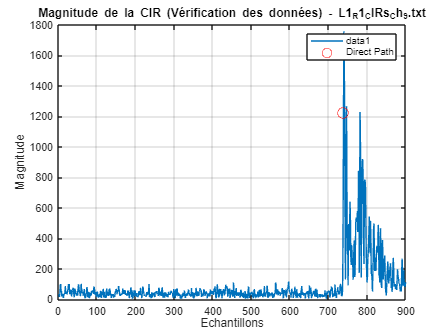

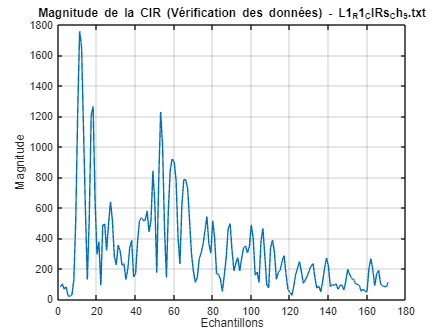

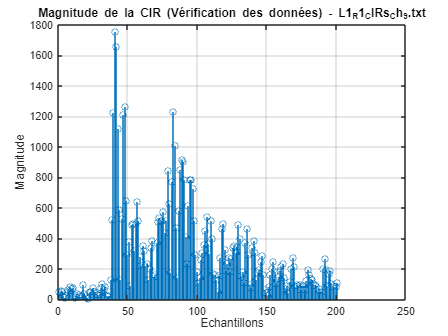

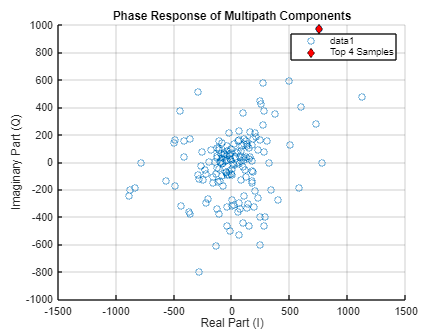

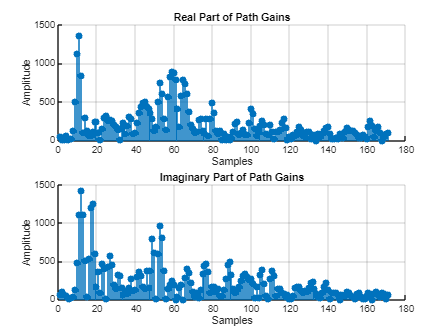

CIR number 7 for L1_R1_CIRs_Ch_9.txt


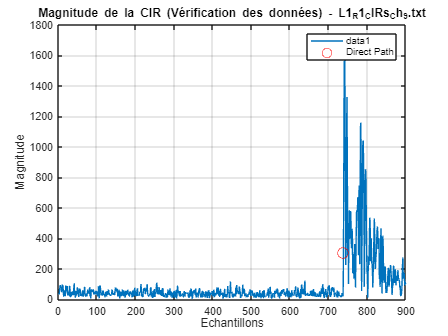

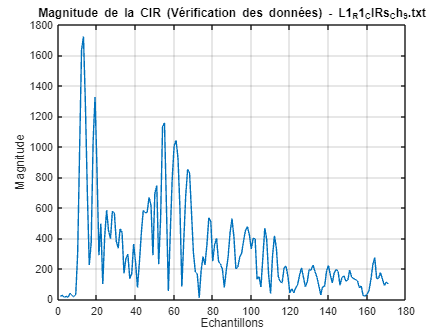

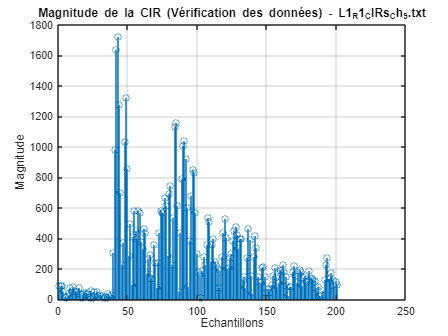

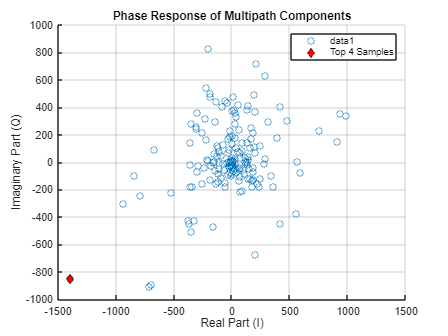

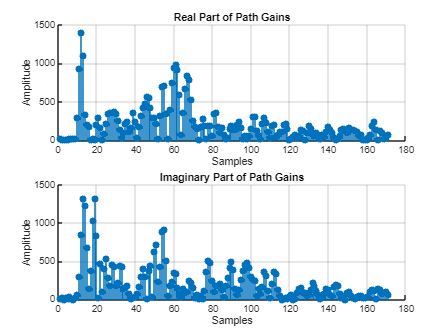

CIR number 8 for L1_R1_CIRs_Ch_9.txt


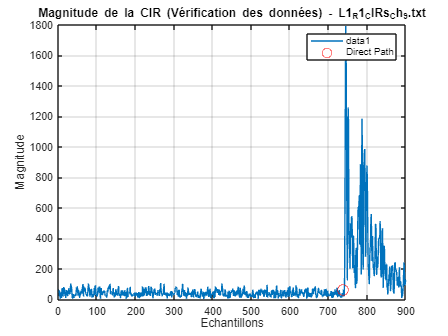

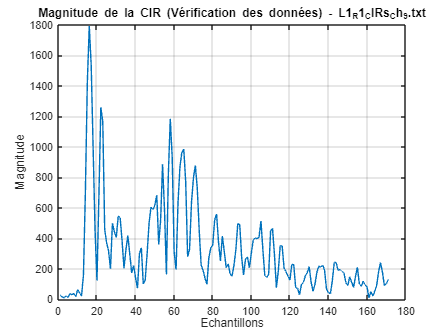

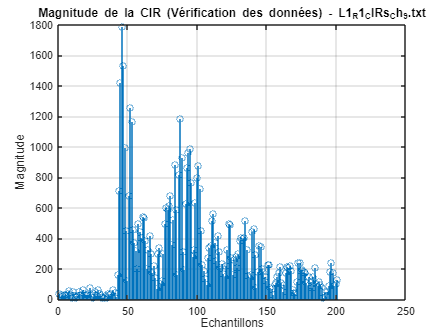

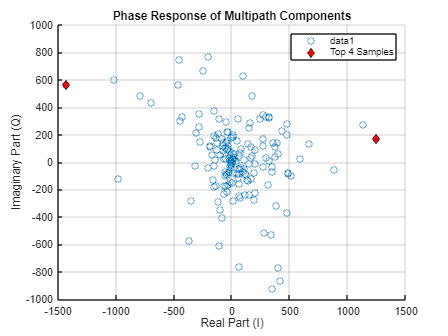

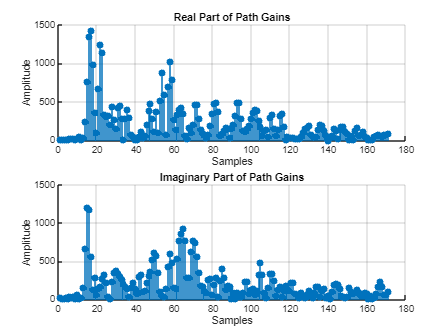

CIR number 9 for L1_R1_CIRs_Ch_9.txt


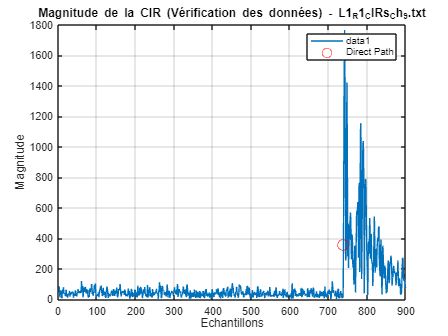

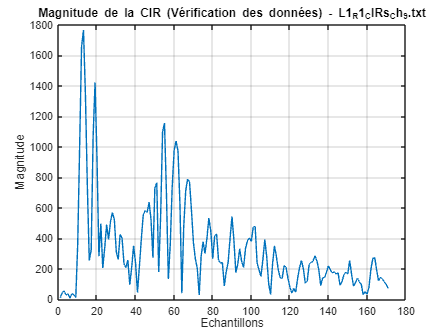

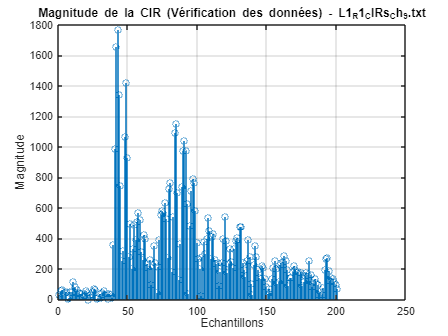

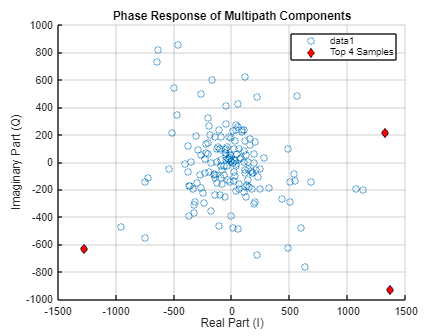

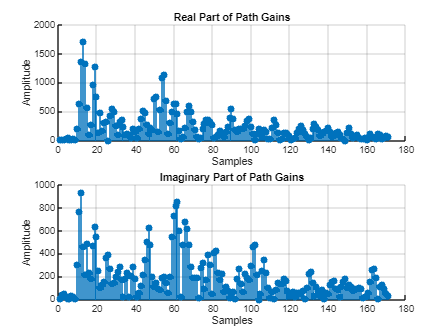

CIR number 10 for L1_R1_CIRs_Ch_9.txt


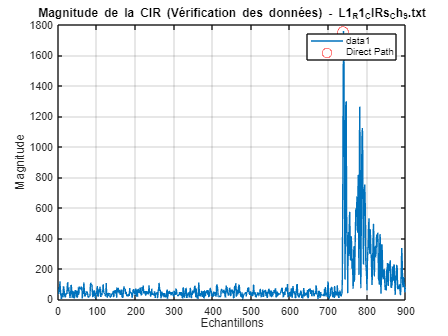

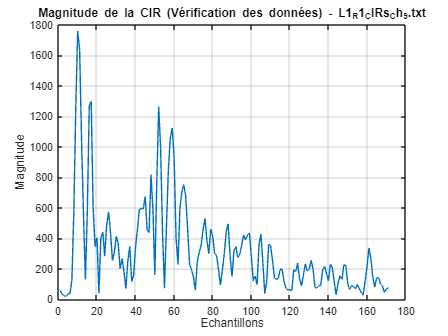

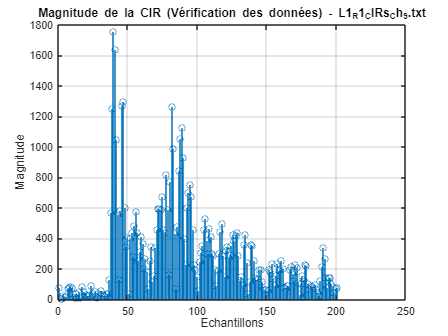

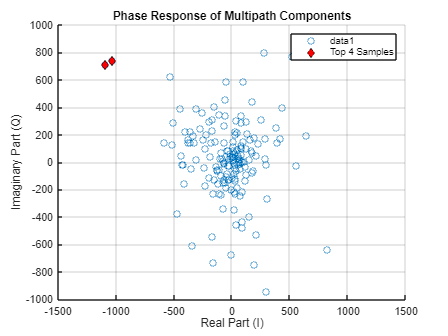

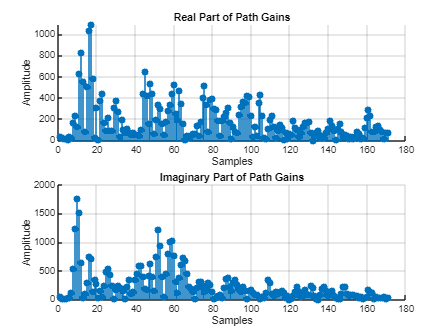

CIR number 11 for L1_R1_CIRs_Ch_9.txt


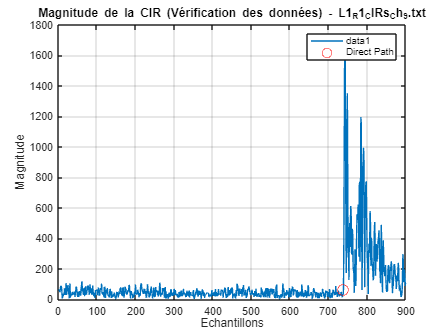

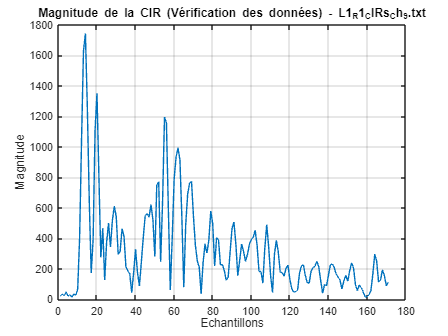

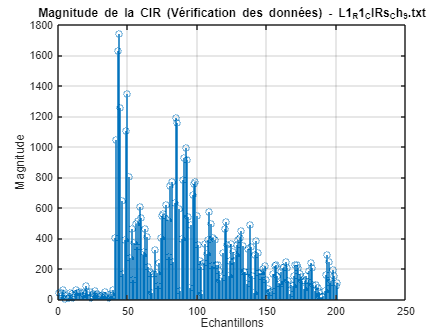

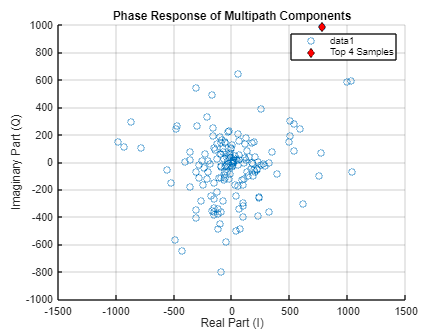

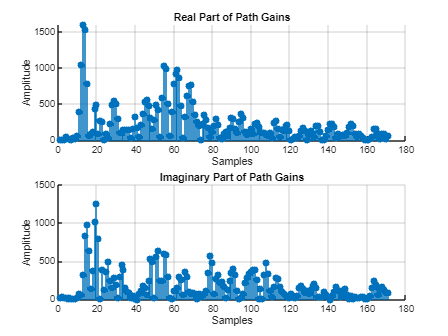

CIR number 12 for L1_R1_CIRs_Ch_9.txt


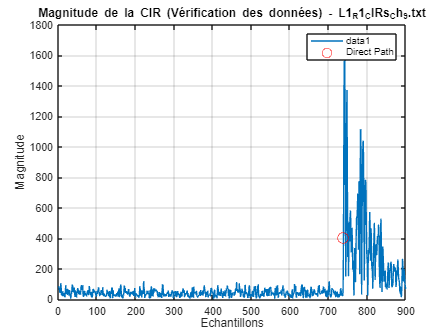

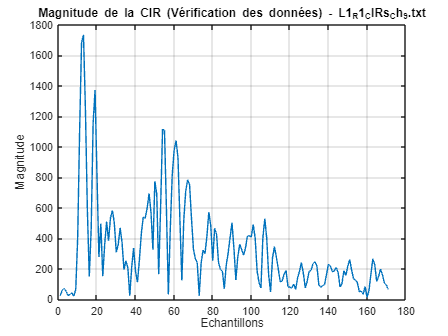

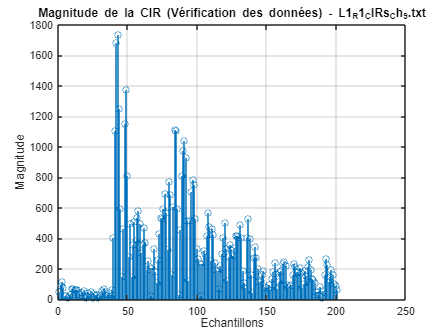

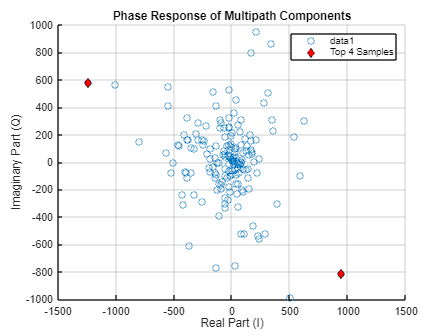

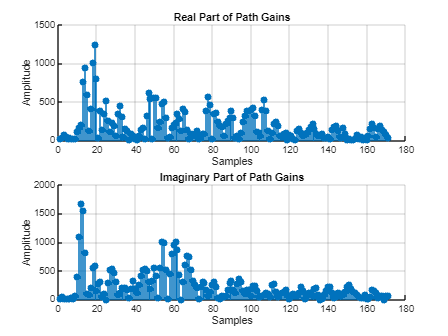

CIR number 13 for L1_R1_CIRs_Ch_9.txt


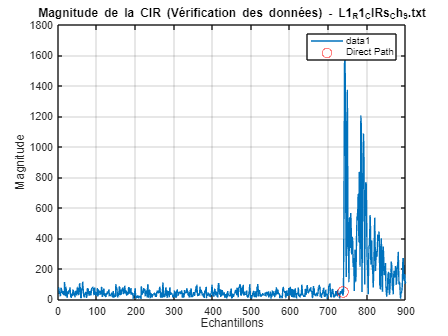

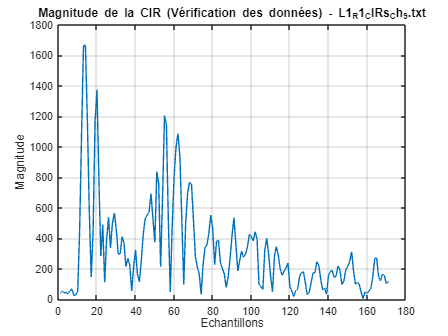

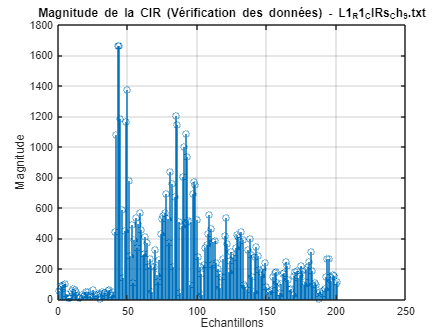

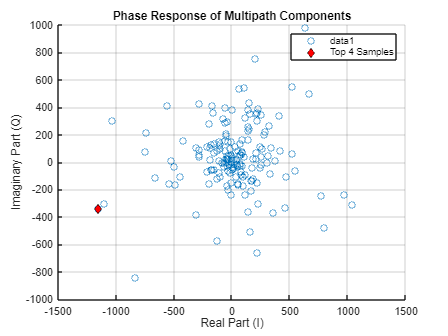

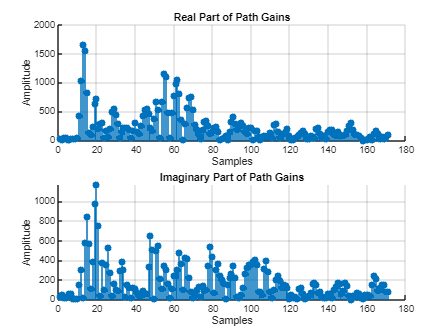

CIR number 14 for L1_R1_CIRs_Ch_9.txt


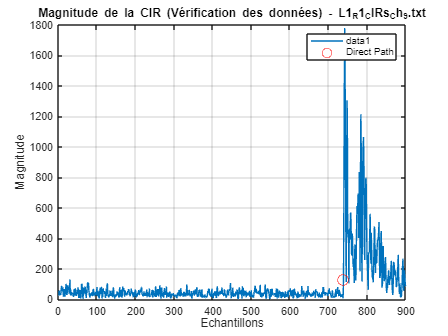

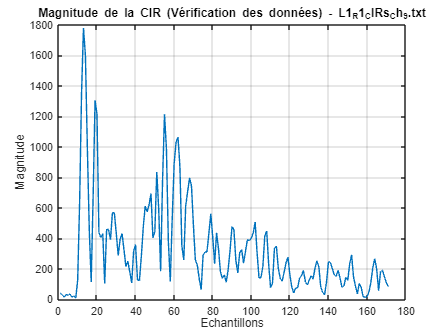

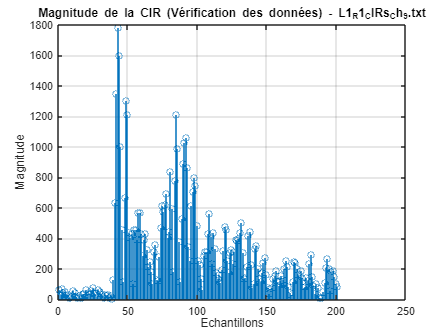

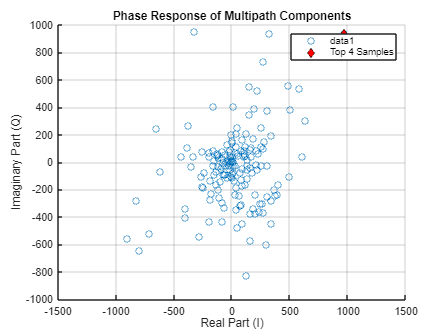

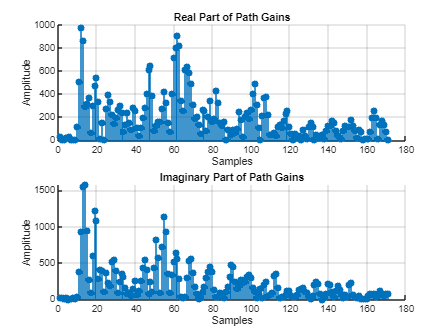

CIR number 15 for L1_R1_CIRs_Ch_9.txt


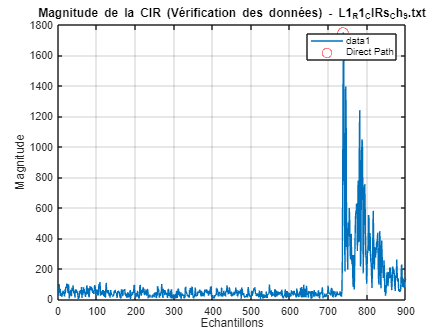

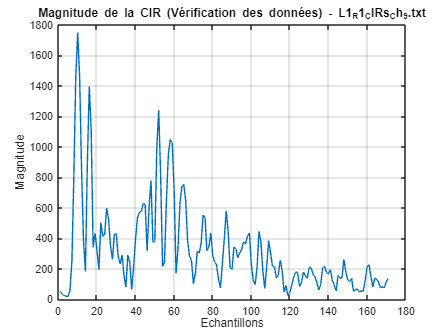

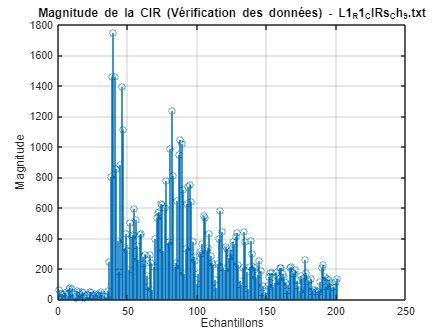

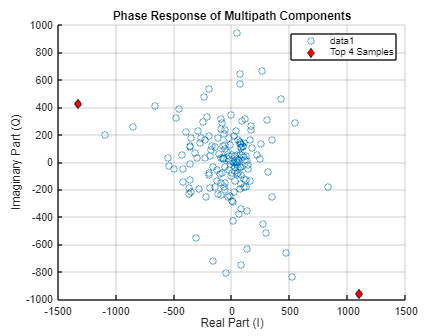

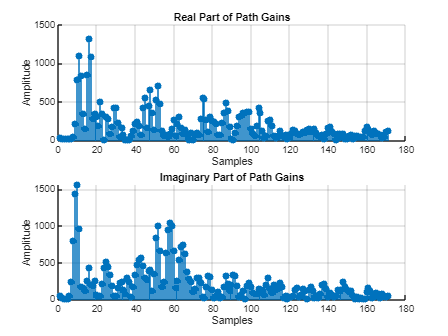

CIR number 16 for L1_R1_CIRs_Ch_9.txt


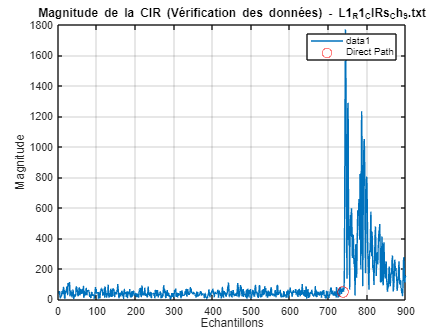

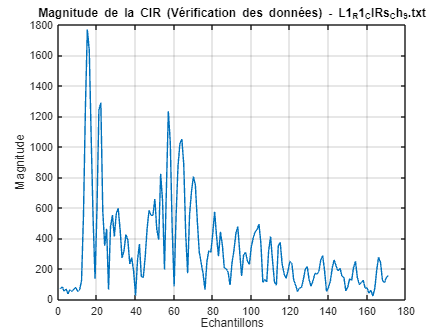

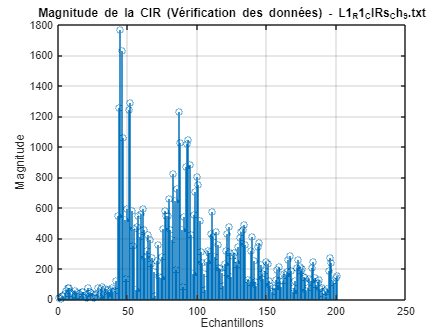

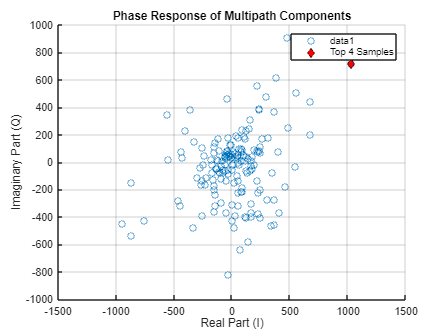

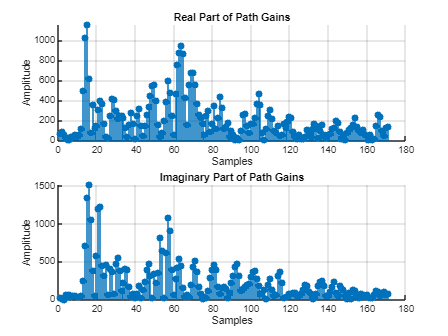

CIR number 17 for L1_R1_CIRs_Ch_9.txt


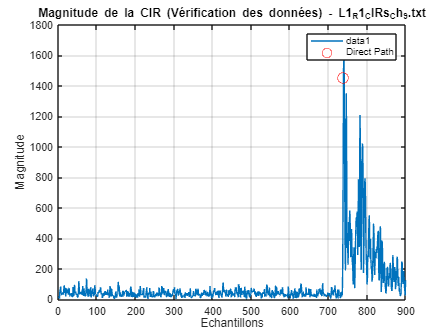

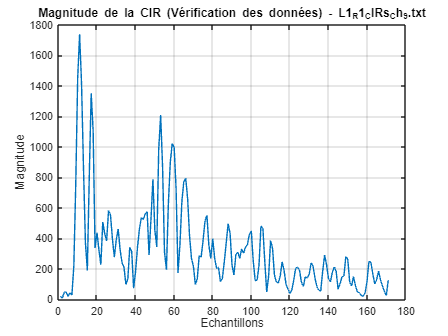

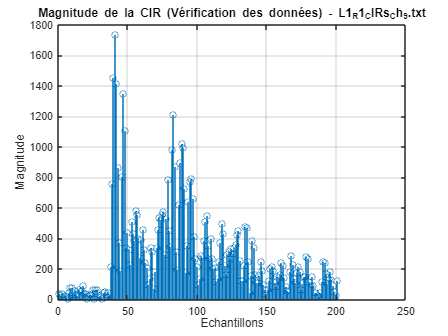

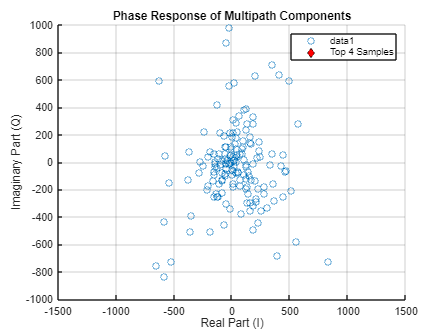

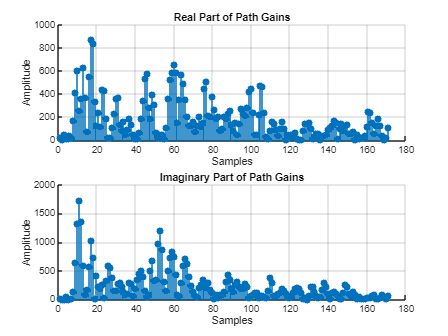

CIR number 18 for L1_R1_CIRs_Ch_9.txt


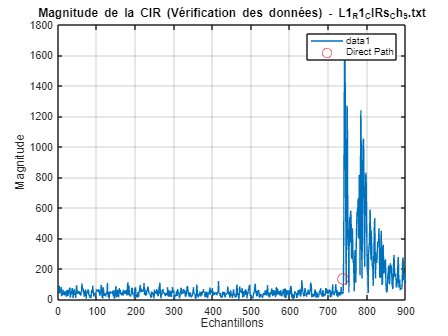

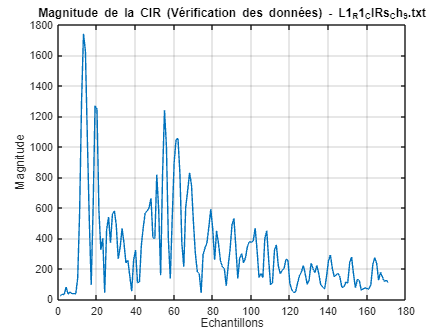

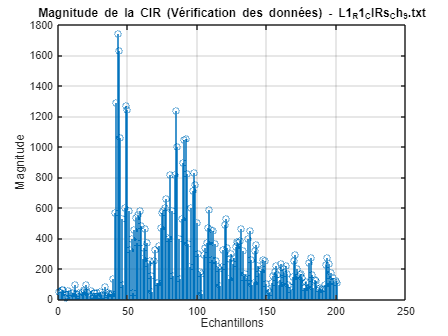

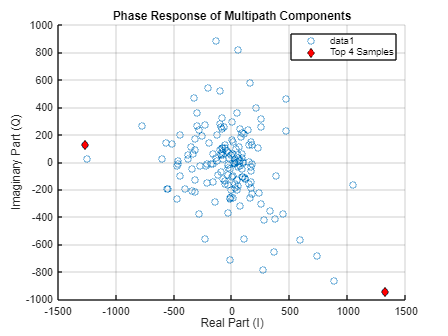

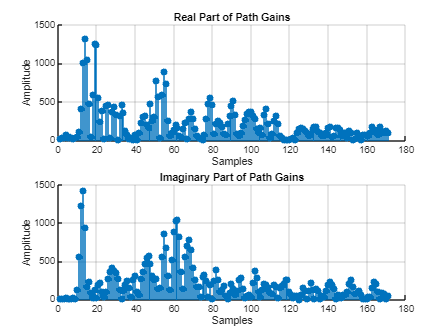

CIR number 19 for L1_R1_CIRs_Ch_9.txt


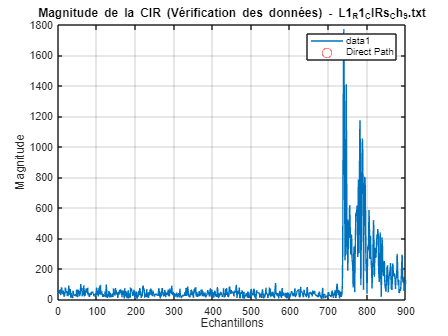

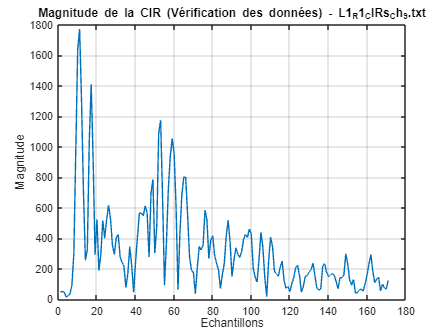

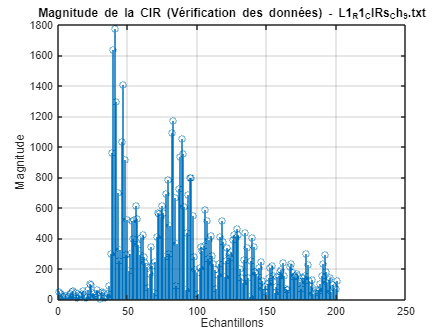

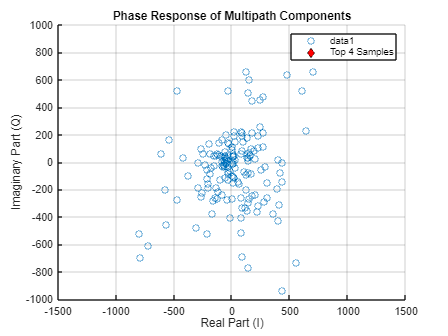

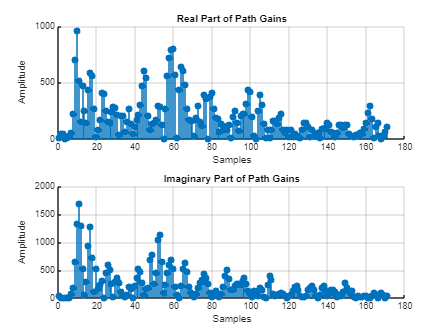

CIR number 20 for L1_R1_CIRs_Ch_9.txt


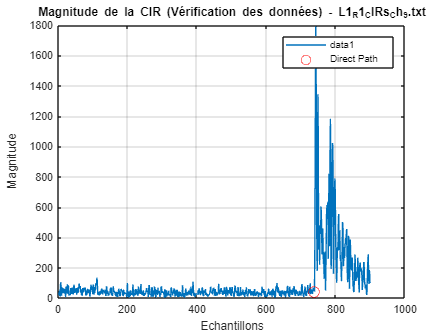

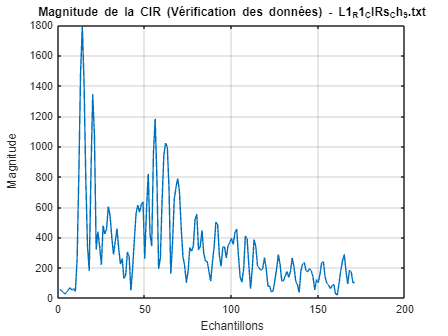

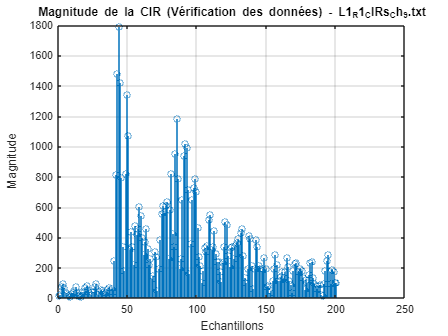

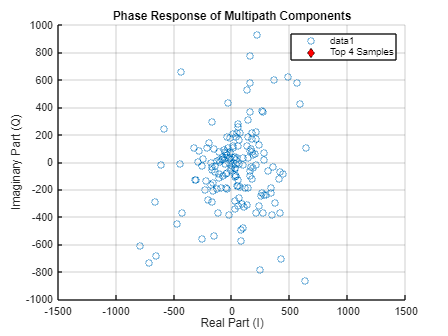

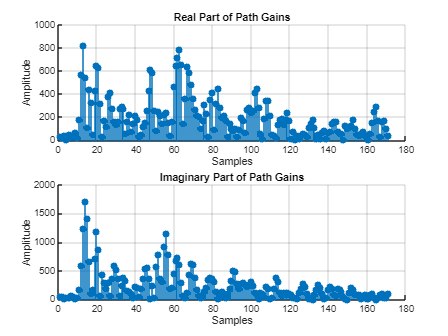

CIR number 21 for L1_R1_CIRs_Ch_9.txt


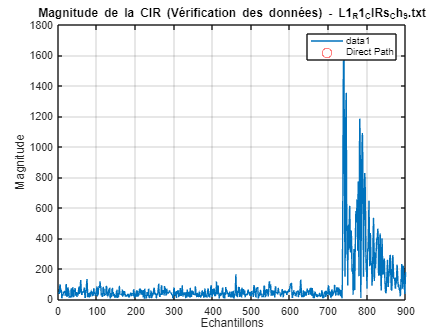

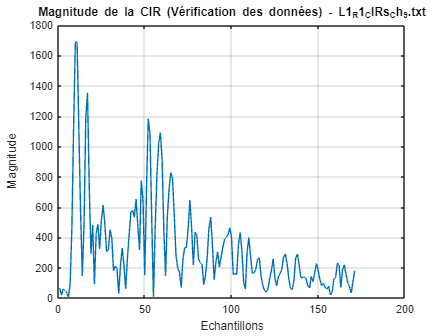

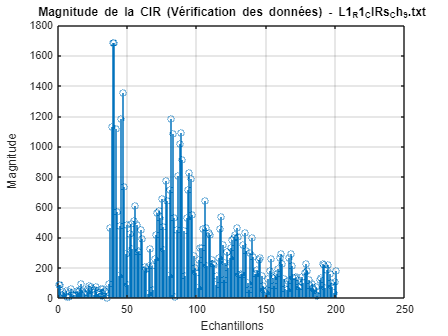

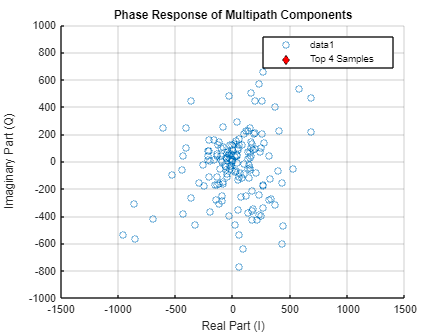

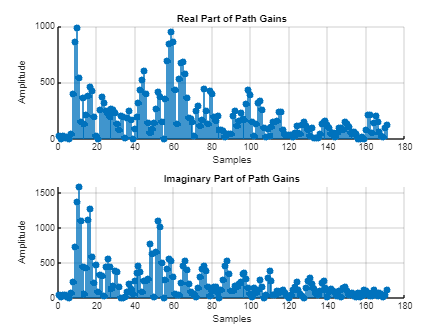

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI

% Description : This MATLAB script reads and processes Channel Impulse 
% Response (CIR) data from a specified file. It calculates the magnitude 
% of the CIR, identifies the direct path for Line-of-Sight (LOS) conditions, 
% and visualizes various aspects of the CIR data. The user is prompted to 
% enter the number of CIRs to display, and the script then plots the CIR 
% magnitude, highlights the direct path, and displays scatter plots of the 
% real and imaginary parts of the multipath components. The script includes 
% functions to detect the first path for both LOS and Non-Line-of-Sight 
% (NLOS) conditions.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    

% Read files and extract data
file_paths = {'L1_R1_CIRs_Ch_9.txt'};

all_CIR_real_all = {};
all_CIR_imag_all = {};

for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurements(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end
disp(['==========================================================================']);               

while true
    % Prompt the user for the number of CIRs to display
    prompt = 'Enter the number of CIRs you want to display or 0 to exit: ';
    numCIRs = input(prompt);
    
    if numCIRs == 0 % Exit if 0 is pressed
        break;
    end
    
    if numCIRs > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end
    
    for CIRNumber = 1:numCIRs
        for i = 1:length(file_paths)
            file_path = file_paths{i};
            CIR_real_all = all_CIR_real_all{i};
            CIR_imag_all = all_CIR_imag_all{i};

            if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
                disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
                disp(['==========================================================================']);               

                % Calculate CIR magnitude
                CIR_real = CIR_real_all{CIRNumber}';
                CIR_imag = CIR_imag_all{CIRNumber}';
                CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);

                % Display CIR magnitude
                figure;
                plot(CIR_magnitude);
                title(['CIR Magnitude (Data Verification) - ', file_path]);
                xlabel('Samples');
                ylabel('Magnitude');
                grid on;

                % Find the direct path index for LOS
                directPathIdx = findFirstPathLOS(CIR_magnitude);

                % Annotate the direct path on the plot
                hold on;
                plot(directPathIdx, CIR_magnitude(directPathIdx), 'ro', 'MarkerSize', 10, 'DisplayName', 'Direct Path');
                legend('show');
                hold off;
                
                % Display the CIR magnitude from sample 730 onwards
                figure;
                plot(CIR_magnitude(730:end));
                title(['CIR Magnitude (Data Verification) - ', file_path]);
                xlabel('Samples');
                ylabel('Magnitude');
                grid on;

                % Display the CIR magnitude from sample 700 onwards using stem plot
                figure;
                stem(CIR_magnitude(700:end));
                title(['CIR Magnitude (Data Verification) - ', file_path]);
                xlabel('Samples');
                ylabel('Magnitude');
                grid on;

                % Visualize the phase response of multipath components
                figure;
                scatter(CIR_real(730:end), CIR_imag(730:end));
                xlabel('Real Part (I)');
                ylabel('Imaginary Part (Q)');
                title('Phase Response of Multipath Components');
                axis([-1500 1500 -1000 1000]); % Set x and y axis limits
                grid on;

                % Highlight top 4 samples
                hold on;
                [~, sortedIdx] = sort(CIR_magnitude, 'descend');
                top4Idx = sortedIdx(1:4);
                scatter(CIR_real(top4Idx), CIR_imag(top4Idx), 'd', 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r', 'DisplayName', 'Top 4 Samples');
                legend;

                % Visualize the phase response of multipath components with subplots
                figure;
                subplot(2,1,1) % Create the first subplot in a 2x1 grid
                hold on;
                stem(abs(CIR_real(730:end)), 'filled');
                xlabel('Samples');
                ylabel('Amplitude');
                title('Real Part of Path Gains');
                grid on;
                hold off;
    
                subplot(2,1,2) % Create the second subplot in a 2x1 grid
                hold on;
                stem(abs(CIR_imag(730:end)), 'filled');
                xlabel('Samples');
                ylabel('Amplitude');
                title('Imaginary Part of Path Gains');
                grid on;
                hold off;
                disp(['==========================================================================']);               
            else
                disp(['Invalid CIR number for ', file_path]);
            end
        end
    end
end

% Function to detect the First Path for LOS condition
function directPathIdx = findFirstPathLOS(CIR_magnitude)
    noiseWindow = 720; % Initial window to estimate noise
    magnitudes_in_noise_window = CIR_magnitude(1:noiseWindow);
    
    % Display magnitude values in the noise window
    disp('Magnitude values in the noise window:');
    disp(magnitudes_in_noise_window);
    
    % Calculate noise variance
    noiseVariance = var(magnitudes_in_noise_window);
    disp(['Variance of magnitudes in the noise window: ', num2str(noiseVariance)]);
    
    % Detect the highest peak
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    % Display debug information
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
    
    thresholdFactor = 3; % Factor to detect significant variance increase
    threshold = noiseVariance * thresholdFactor;
    
    % Iterate over samples after the noise window to detect variance increase
    directPathIdx = noiseWindow;
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]);
end

% Function to detect the First Path for NLOS
function directPathIdx = findFirstPathNLOS(CIR_magnitude)
    % Detect the highest peak
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    % Estimate noise variance
    noiseWindow = 720; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    % Adjust threshold based on LOS variance
    thresholdFactor = 3; % Factor to detect significant variance increase
    threshold = noiseVariance * thresholdFactor;
    % Initialize direct path index with the highest peak index
    directPathIdx = highestPeakIndex;
    % Display debug information
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
   
    % Iterate over samples after the noise window to detect variance increase
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]); 
end
